# Ejercicio 4

En este ejercicio aplicaremos el mismo concepto que en el ejercicio 2 pero aplicado a cada uno de los canales de color.

Leemos la imagen y obtenemos los tres canales de color. La imagen que utilizaremos es de 640x480 píxeles de tamaño.

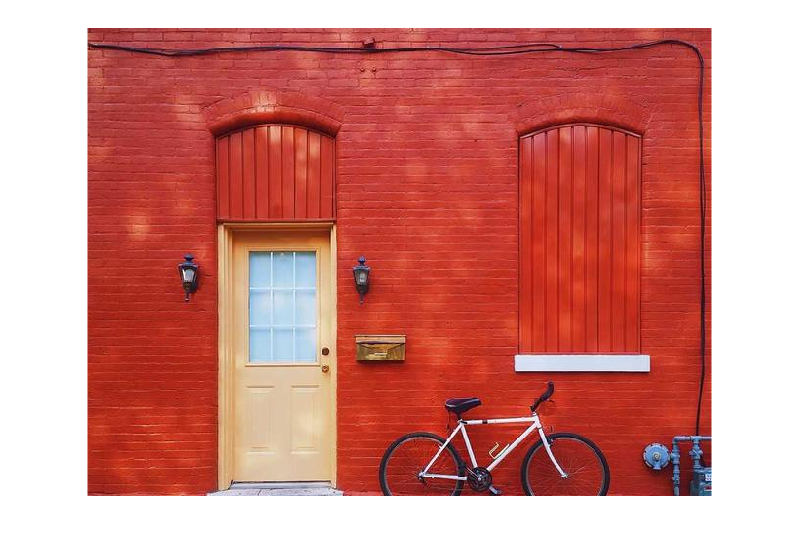

clearvars; close all;
image = imread('image4.jpg');
figure(); imshow(image);

imR = double(image(:,:,1));
imG = double(image(:,:,2));
imB = double(image(:,:,3));

Dividimos la imagen en sub-imágenes (o ventanas) del mismo tamaño. Escogemos un tamaño para que sea divisor de la resolución de la imagen con n.

[r,c,~] = size(image);
n = 16;
rsizes = n*ones(1,r/n);
csizes = n*ones(1,c/n);
wR = mat2cell(imR, rsizes, csizes);
wG = mat2cell(imG, rsizes, csizes);
wB = mat2cell(imB, rsizes, csizes);

De este modo, tenemos `r/n * c/n` ventanas de `n` filas y `n` columnas, es decir, de n*n píxeles. De este modo, si definimos el tamaño de las ventanas en 16 píxeles, tendremos `640/16 * 480/16 = 40 * 30 = 1200 ventanas (N) `de `256 píxeles` cada una.

Formamos los patrones a partir de cada una de las sub-imágenes. Transformamos las ventanas en vectores fila de n*n elementos y lo guardamos en `patterns`.

counter = 1;
for i=1:r/n
    for j=1:c/n
        pR(counter, :) = reshape(wR{i,j}, [1 n*n]);
        pG(counter, :) = reshape(wG{i,j}, [1 n*n]);
        pB(counter, :) = reshape(wB{i,j}, [1 n*n]);
        counter = counter + 1;
    end
end

En este punto, las variable `p` tiene N filas y n*n columnas. Cada fila representa una ventana colocada en forma de vector.

Ahora hay que generar la red neuronal autoorganizada. Definimos la rejilla y las épocas y la entrenamos con los patrones en forma de columnas.

rejilla = [10 10];
redR = selforgmap(rejilla);
redR.trainParam.epochs=100;
redG = selforgmap(rejilla);
redG.trainParam.epochs=100;
redB = selforgmap(rejilla);
redB.trainParam.epochs=100;

% Training
redR = train(redR, pR');
redG = train(redG, pG');
redB = train(redB, pB');

% Weights matrix
WR = redR.IW{1};
WG = redG.IW{1};
WB = redB.IW{1};

Ahora debemos seleccionar para cada ventana la ventana ganadora. Para ello utilizamos `sim(red, aux)` donde `aux` es la ventana transformada en vector columna.

for i=1:r/n
    for j=1:c/n
        auxR = reshape(wR{i,j}, [n*n 1]);
        auxG = reshape(wG{i,j}, [n*n 1]);
        auxB = reshape(wB{i,j}, [n*n 1]);
        idxR = find(sim(redR, auxR));
        idxG = find(sim(redG, auxG));
        idxB = find(sim(redB, auxB));
        nwR{i,j} = reshape(WR(idxR, :), n, n);
        nwG{i,j} = reshape(WG(idxG, :), n, n);
        nwB{i,j} = reshape(WB(idxB, :), n, n);
    end
end

Obtenemos la imagen a partir de las ventanas seleccionadas y comparamos resultados.

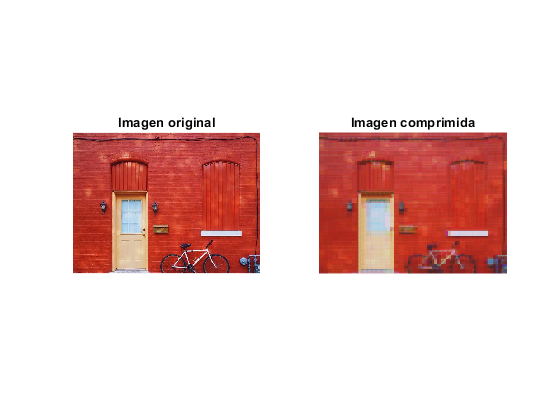

nimR = uint8(cell2mat(nwR));
nimG = uint8(cell2mat(nwG));
nimB = uint8(cell2mat(nwB));
nim(:,:,1) = nimR;
nim(:,:,2) = nimG;
nim(:,:,3) = nimB;
figure(); 
subplot(1,2,1); imshow(image); title('Imagen original');
subplot(1,2,2); imshow(nim); title('Imagen comprimida');